ЛАБОРАТОРНА РОБОТА №5

з навчальної дисципліни «Математичне моделювання систем і процесів»

Виконав:

Студент 5 курсу

Групи ФФ-21мн

Бондар О.В.

Перевірив:

Гордійко Н.О.

Варіант №1 

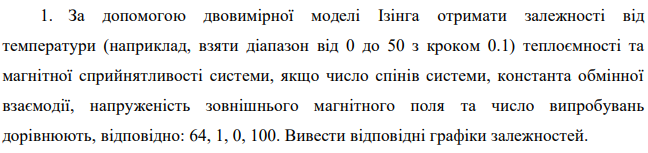

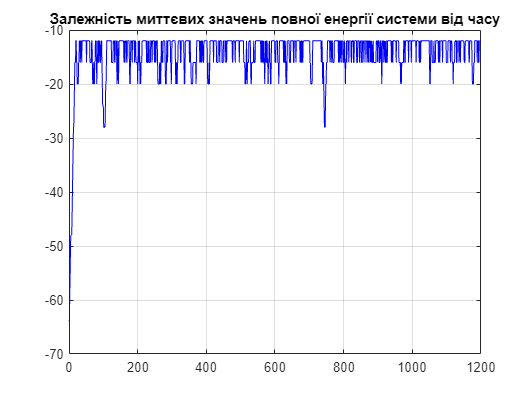

clearvars;
Nspin=64; % число спінів системи
J=1; % константа обмінної взаємодії
h=0; % зовнішнє поле
Esi=-10; % задання кінцевого значення енергії системи
NTrial=100; % кількість випробувань
% обчислення миттєвих значень: повної енергії системи (Es), енергії демона (Ed),
% намагніченості (SpM) та середнього числа прийняття рішень (Accept)
[Es Ed SpM Accept]=Ising(Nspin,J,h,Esi,NTrial);
% візуалізація залежностей миттєвих значень повної енергії системи та
% енергії демона від часу
i=1:1200;
figure; 
plot(i,Es(i), 'b'); 
grid
title('Залежність миттєвих значень повної енергії системи від часу');

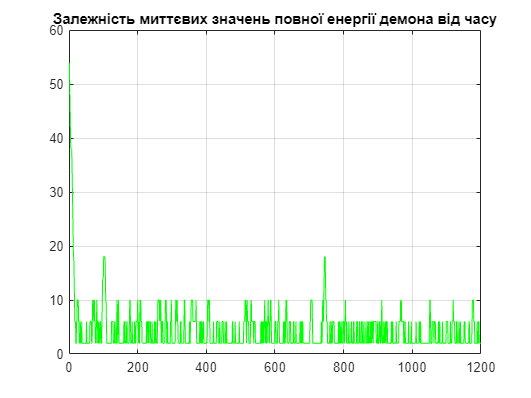


figure; 
plot(i,Ed(i), 'g'); 
grid
title('Залежність миттєвих значень повної енергії демона від часу');


% обчислення розподілу імовірностей миттєвих значень енергії демона 
Nint=50; i=1:0.1:Nint;
x1=min(Ed); 
x2=max(Ed); 
x=x1+(x2-x1)/Nint*i;
h=hist(Ed,x);

% визначення та візуалізація функції, що описує розподіл імовірності
Fun=@(u,z) u(1)*exp(-u(2)*z);
beta=nlinfit(x,h,Fun,[10000 0.05]);

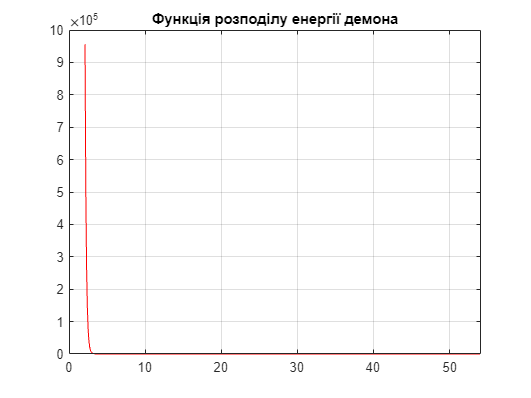


figure; 
bar(x,h); 
colormap white; 
hold on
Ni=500;
j=1:Ni;
X(j)=x1+(x2-x1)/Ni*j;

plot(X,Fun(beta,X),'r'); 
grid; 
title('Функція розподілу енергії демона');

Emean=mean(Es)/Nspin; % обчислення середньої намагніченості на 1 спін
Mean=mean(SpM)/Nspin; % обчислення середньої енергії на 1 спін
Tmean=2/log(1+2./mean(Ed)); % обчислення температури системи


